"这个函数能画出信号的3D-Hilbert谱图"
signa1 = wav_data_r(:,1)';
imf = emd(wav_data_r,'Display',1);

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |    0.0016558   |  SiftMaxRelativeTolerance
      2      |        2     |      0.11607   |  SiftMaxRelativeTolerance
      3      |        2     |     0.055587   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10067   |  SiftMaxRelativeTolerance
      5      |        2     |     0.037406   |  SiftMaxRelativeTolerance
      6      |        2     |     0.070237   |  SiftMaxRelativeTolerance
      7      |        2     |     0.053823   |  SiftMaxRelativeTolerance
      8      |        2     |      0.15671   |  SiftMaxRelativeTolerance
      9      |        2     |      0.05084   |  SiftMaxRelativeTolerance
     10      |        2     |     0.043837   |  SiftMaxRelativeTolerance
分解停止，因为提取的固有模态函数数目达到最大。


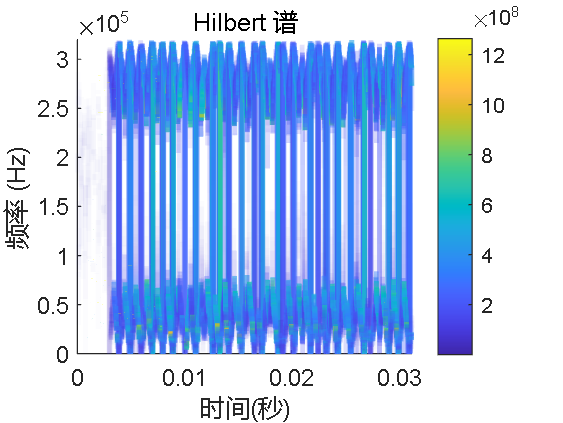

fs = 640e3;
hht(imf,fs);

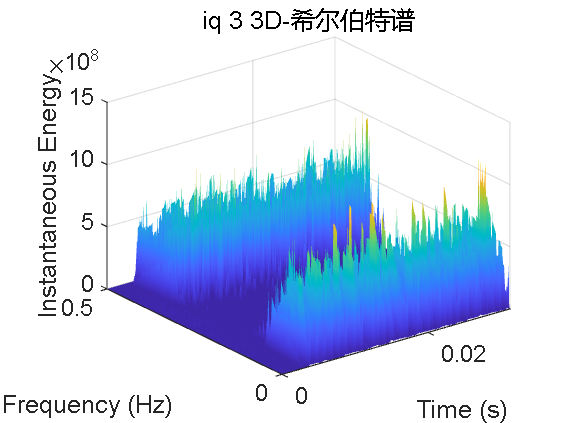

[hs,f,t,imfinsf,imfinse] = hht(imf,fs);
mesh(t,f/fs,hs,'EdgeColor','none','FaceColor','interp')
xlabel('Time' );
ylabel('Frequency Hz');
zlabel('Energy');
title('iq 3 3D-希尔伯特谱')
xlabel('Time (s)')
ylabel('Frequency (Hz)')
zlabel('Instantaneous Energy')

bar(hs)
% colorImage = imread("D:\CUserslyyDesktop\pinpu.jpg");  
%   
% 将彩色图像转换为灰度图像 
% grayImage = rgb2gray(colorImage);  
%   
% % 显示灰度图像  
% imshow(grayImage);  
%   
% matlab 中的稀疏矩阵，将稀疏矩阵中的所有非零值处于最大值然后乘255，返回一个稀疏矩阵
% % 
% x = signa1;
% figure(1)
% imf = vmd(x);
% [p,q] = ndgrid(t,1:size(imf,2));
% plot3(p,q,imf)
% title('iq1')
% grid on
% xlabel('Time Values')
% ylabel('Mode Number')
% zlabel('Mode Amplitude')
% title('iq2')
% figure(2)
% hht(imf,fs)